# Rad229 - Lecture 7:  Signal-to-Noise Ratio

## lec7_01.m:  Noise in k-space and Image Space

Construct NxN k-space of complex noise, and show how this propagates to image space, and to a magnitude image.


% Lecture 7, Example 01
% 
% Generate noise in K-space with normal distribution with expected value of
% 0. To check from the image, the sigma is of the same value.
%
nsig = 1;	 % Standard deviation/sigma of noise (shared by real and imaginary)
nmean = 0;   % Expected value of noise (shared by real and imaginary)

N = 256;	% Image/k-space size.

kr = randn([N,N])*nsig + nmean;		% Generate gaussian noise (real part)
ki = randn([N,N])*nsig + nmean;		% Generate gaussian noise (imag part)
k = kr+1i*ki;			            % Combine to generate complex k space value

tt=sprintf('Std.Dev of noise in k-space is %.5g (real), %.5g (imag) and %.5g (magnitude)', std(kr(:)),std(ki(:)), std(abs(k(:)))); 

disp(tt);		% Display calculated stats

Std.Dev of noise in k-space is 0.99756 (real), 0.99846 (imag) and 0.65483 (magnitude)



im = N * ift(k);	% iFFT with scaling of sqrt(N*N)=N

tt=sprintf('Std.Dev of noise in k-space is %.5g (real), %.5g (imag) and %.5g (magnitude)', std(real(im(:))),std(imag(im(:))), std(abs(im(:))));
disp(tt);

Std.Dev of noise in k-space is 0.99593 (real), 1.0001 (imag) and 0.65457 (magnitude)


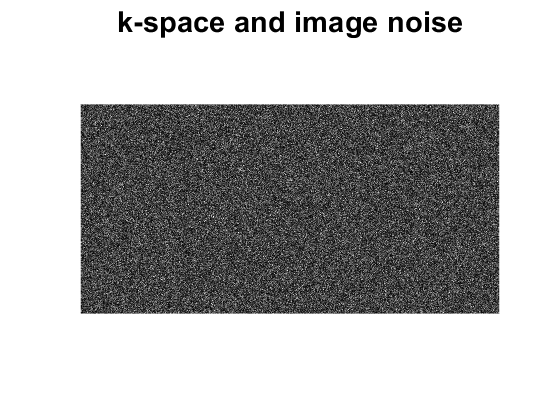


%
% -- Calculate noise as a function of SNR, with magnitude images
%
s=[0:0.1:10];		% s = Signal, so same as SNR if nsig==1
for p=1:length(s)
  mn(p) = mean(abs(im(:)+s(p)));	% Mean of magnitude signal
  sd(p) = std(abs(im(:)+s(p)));		% Std.deviation of magnitude signal
end;

set(0,'defaultAxesFontSize',20);	% Default font sizes
set(0, 'DefaultLineLineWidth', 2);	% Default line width

figure(1);			
dispim(cat(2,k,im)); axis equal;	% Display
title('k-space and image noise');	% 
axis off;

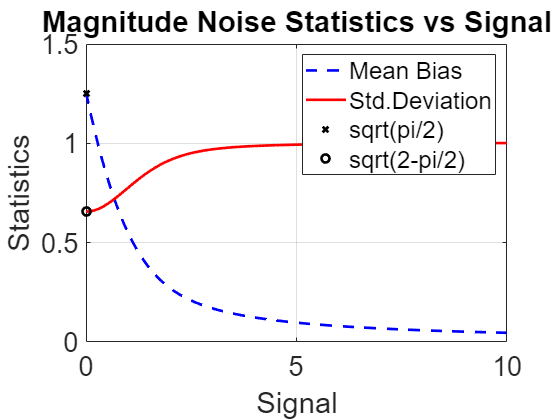


figure(2);
plot(s,mn-s,'b--',s,sd,'r-'); 		% Plot mean ans std.deviation
hold on;
plot(0,sqrt(pi/2)*nsig,'kx');		% Plot expectd mean
plot(0,sqrt(2-pi/2)*nsig,'ko');		% Plot expected std.dev
hold off;
leg1=legend('Mean Bias','Std.Deviation','sqrt(pi/2)','sqrt(2-pi/2)');
lplot('Signal','Statistics','Magnitude Noise Statistics vs Signal');

setprops;




## lec7_02.m  Plot histograms of noisy background and signal

% Lecture 7, Example 02
%
% Plot noise distributions.
%

close all;
figure(1);
ghist(real(im(:)),[],[],[],'Histogram of Real(noise)');

span_norm_x = 4

y = 0.0318


figure(2);

rhist(abs(im(:)),[],[],[],'Histogram of abs(noise)');

figure(3);
ghist(abs(im(:)+4),[],[],50,'Histogram of abs(4+noise)');


## lec7_03.m   Variable Averaging in k-Space

This example is to show the effect of sampling with a higher averaging factor y in some parts of k-space than others.  It is not intuitive, but this concept comes up in radial sampling again.

% Lecture 7, Example 03
% 
% Sample central half of k-space twice, outer half once.
%

close all;
N = 256;
ksp = randn(1.5*N,N)+i*randn(1.5*N,N);  % complex, sigma=1
ksp(N/4+1:3*N/4,:) = 0.5* ( ksp(N/4+1:3*N/4,:) + ksp(N+1:end,:)); % Average
ksp = ksp(1:N,:);       % Crop

figure(1); 
set(0,'defaultAxesFontSize',20);        % Default font sizes
dispim(ksp);
title('k-space');

im = 1/N*ft(ksp);
figure(2); 
set(0,'defaultAxesFontSize',20);        % Default font sizes
dispim(im);
title('Image Noise');

figure(3);
mn = mean(real(im(:)));
sd = std(real(im(:)));
ghist(real(im(:)),0,1/sqrt(1.5),[],'Histogram of Real(noise)','Data','\sigma = 1/sqrt{1.5}');
tt=sprintf('Mean and Std.Dev are %g and %g', mn, sd); disp(tt);
tt=sprintf('Std.Dev * sqrt(1.5) is %g',sd*sqrt(1.5)); disp(tt);
tt=sprintf('sqrt(9/8) = %g',sqrt(9/8)); disp(tt);


Note that the histogram is a little wider than the red Gaussian trace, which has a standard deviation of sqrt(2/3), meaning the SNR effiicency is not as high is we would hope from sampling for 50% longer.

## lec7_04.m  SNR Relationships

Here we change the FOV, resolution, and averaging.  We show calculation of signal statistics using a foreground/background approach and using multiple replicas to calculate the actual distribution at a pixel.

% Lecture 7, Example 04
% 
% Starting with k-space, change NEX, FOV, Resolution to 
% test the impact on SNR
%
% -- Defaults
close all;
set(0,'defaultAxesFontSize',8); % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width

% -- Generate k-space for a square object with large FOV
N=256;                  % Image size (square)
siglevel=10;             % Signal level in square
im = zeros(N,N);
im(N/2-N/8+1:N/2+N/8, N/2-N/8+1:N/2+N/8) = ones(N/4,N/4)*siglevel;
ksp = N*ift(im);        % iFFT, normalized

roi = find(im(:)>0.5);  % Include all points in original image above 0.5
bgroi = [1:8*N];        % First 8 lines, assumed to be in background
 
% -- Add noise, and repeat multiple times
Nreps=500;
kall = zeros(N,N,Nreps);
for n = 1:Nreps kall(:,:,n)=ksp; end;
kall = kall + randn(N,N,Nreps) + i*randn(N,N,Nreps);  % Complex Noise, sigma=1

% -- 1. Convert to "reference" image and measure SNR
imall = 0*kall;
for n=1:Nreps
  imall(:,:,n) = (1/N)*ft(kall(:,:,n)); % FT all images
end;

im1 = abs(imall(:,:,1));
roisig = mean(im1(roi));        % Get mean signal in foreground
bgmean = mean(im1(bgroi));      % Get mean background
snrest = roisig / (bgmean/sqrt(pi/2));  % Estimate SNR
tt=sprintf('Estimated SNR is %g',snrest); disp(tt);

figure(1);
[mn,sd] = lec7kimhist(kall(:,:,1),'Reference',abs(im1(roi)));
refsnr=mn/sd;

% -- 2. Repeat measurement with multiple reps

pixsigs = imall(N/2,N/2,:);     % Get one pixel, all Nreps signals

figure(2); 
[mn,sd] = lec7kimhist(mean(kall(:,:,:),3),'Replicas',abs(pixsigs),refsnr);


% 3. Reduce FOV and measure Image SNR
% NOte that we will reconsruct the the original FOV here, could crop in y.

krFOV = kall(:,:,1);            % One k-space here.
krFOV(2:2:end,:)=0;             % Discard even lines (set to 0)
imrFOV = (2/N)*ft(krFOV);    % Normalize for N x (N/2)   

figure(3); 
[mn,sd] = lec7kimhist(krFOV,'reduced FOV',abs(imrFOV(roi)),refsnr);


% 4. Reduce resolution and measure Image SNR
krres = kall(:,:,1);            % One k-space here.
krres = zpadcrop(krres,[N/2,N/2]);% Crop k-space
kspr = zpadcrop(ksp,[N/2,N/2]);   % Crop denoised k-space for ROI

imrres = (1/N)*ft(krres);    % Same normalizing (same k-space)
imrroi=0*imrres;
imrroi(N/4-N/16+3:N/4+N/16-2, N/4-N/16+3:N/4+N/16-2) = ones(N/8-4,N/8-4)*siglevel;
rroi = find(abs(imrroi(:))>0.5);

figure(4); 
[mn,sd] = lec7kimhist(krres,'reduced res',abs(imrres(rroi)),refsnr);
%subplot(2,2,4);
%imroicheck = 0*imrroi; imroicheck(rroi)=1; 
%dispim(imroicheck);

% 5. Do averaging and measure Image SNR
kavg = mean(kall(:,:,1:2),3);   % Average 2 k-spaces
imavg= (1/N)*ft(kavg);          % Normalize NxN

figure(5); 
[mn,sd] = lec7kimhist(kavg,'Averaged(2x)',abs(imavg(roi)),refsnr);


Exercise:

1) Try more averages.  

2) Try reducing the signal level so that bias is an issue.

## lec7_05.m  2-Coil R=1 SENSE Weights

This example tries to show how SENSE weights are calculated.

% Lecture 7, Example 05
% 
% A simple 2-coil example of optimal weights.
close all;
set(0,'defaultAxesFontSize',14); % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width
S = [2;1];      % Sensitivities of 2 coils (at a pixel)

% -- Test all relative weights of these coils

w1 = [0:0.01:0.95];
w2 = 1-w1;

for k = 1:length(w1)
  W = [w1(k) 1-w1(k)];
  sig = W*S;            % Signal
  nvar = sum(W.^2);     % Variance
  snr(k) = sig/sqrt(nvar);      %
end;


[y,yi] = max(snr);
plot(w1,snr,'r-',w1,w1./w2,'b--',w1(yi)*[1 1],[0 4],'k-');
lplot('Weight on Coil 1','SNR','SNR vs weights');
legend('SNR','W1/W2','optimal');
axis([0 1 0 1.25*y]);

[W,g,imn] = senseweights(S);
disp(['SENSE Weights']); disp(W);
SENSEsnr = (W*S)/sqrt(imn);
disp('SENSE SNR'); disp(SENSEsnr);


Exercises:

1) Try with different sensitivities

## lec7_06.m    2D SENSE Image Example

This example gives you some code that you can play around with all aspects of a SENSE reconstruction to look at noise.  It is a bit long, but commented so that you can see the steps.  Note that much of the characterization is done long before the signal is reconstructed!

% Lecture 7, Example 06
% 
% SENSE reconstruction with 4 coils and various R

% -- Start by making a nice image that will show aliasing etc

clear; close all;
Nruns = 10;
N=256;
Nc=4;   % Hard-coded anyway, but cleaner.
R=3;
psi = eye(Nc);  % Equal, uncorrelated noise
cscale = 30000; % Roughly normalize coil sensitivity

set(0,'defaultAxesFontSize',8); % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width

im1 = 5*circ(N/2,.33*N/2);
im2 = 10*diamond(N/2,.8*N/2);
im3 = 12*diamond(N/2,.5*N/2);
im4 = 10*circ(N/2,.25*N/2);
im = cat(1,cat(2,im1,im2),cat(2,im3,im4));

%dispim(im); title('Truth Image');

% -- Coil Sensitivities
coils=zeros(N,N,4);
coils(:,:,1) = gaussian2d(N,[N/2,N/4],N/4);
coils(:,:,2) = gaussian2d(N,[N/4,N/2],N/4);
coils(:,:,3) = gaussian2d(N,[3*N/4,N/2],N/4);
coils(:,:,4) = gaussian2d(N,[N/2,3*N/4],N/4);
coils = cscale * coils;         % Roughly normalize
figure(1);
% -- Channel images
cims = 0*coils;
for k=1:4 
  cims(:,:,k) = coils(:,:,k).*im; 
  subplot(2,4,k); dispim(coils(:,:,k)); tt = sprintf('Coil Sensitivity %d',k); title(tt); 
  axis equal; axis off;
  subplot(2,4,k+4); dispim(cims(:,:,k)); tt = sprintf('Sig %d',k); title(tt); 
  axis equal; axis off;
end;

% -- Make sure Ny is divisible by R, for simplicity
Ny = floor(N/R)*R;
im = im(1:Ny,:);
coils = coils(1:Ny,:,:);
cims = cims(1:Ny,:,:);

% -- Make Aliased images and sensitivities.
cims = reshape(cims, Ny/R,R,N,Nc);
coils= reshape(coils,Ny/R,R,N,Nc);

figure(2);
coils = permute(coils,[1,3,4,2]);       % reorder sensitivities
for r=1:R
  for c=1:Nc
    subplot(R,Nc,Nc*(r-1)+c);
    dispim(coils(:,:,c,r)); tt=sprintf('Sens Ch %d, p=%d',c,r); title(tt);
    axis equal; axis off;
  end;
end;

% -- Calculate the weights
disp('Calculating weights');
weights = zeros(Ny/R,N,R,Nc);
gfact = zeros(Ny/R,N,R);
noise = zeros(Ny/R,N,R);
for y=1:Ny/R
  for x=1:N
    [w,g,n] = senseweights(squeeze(coils(y,x,:,:)));
    weights(y,x,:,:)=w;

    if (1==0) && (x==128) && (y==60) 
        sz = size(squeeze(coils(y,x)));
        disp(sz);
        disp(w); 
    end;
    gfact(y,x,:)=g;
    noise(y,x,:)=sqrt(diag(n));
  end;
end;

% -- Plot the weights
figure(3);
for r=1:R
  for c=1:Nc
    subplot(R,Nc,Nc*(r-1)+c);
    dispim(weights(:,:,r,c)); tt=sprintf('Weight Ch %d, p=%d',c,r); title(tt);
    axis equal; axis off;
  end;
end;

figure(4);
gfact = permute(gfact,[1,3,2]); gfact = reshape(gfact,Ny,N);
noise = permute(noise,[1,3,2]); noise = reshape(noise,Ny,N);
subplot(1,2,1); dispim(gfact); axis off; title('Calculated g-factor');
subplot(1,2,2); dispim(noise); axis off; title('Calculated Noise');
 

% ========= ACTUALLY DO A RECONSTRUCTION!! =======


cims =  permute(cims,[1,3,4,2]);        % reorder coil images
cims =  sum(cims,4);                    % ALIAS IMAGES!!

allsenseims = zeros(Ny,N,Nruns);                % Store all!
% -- Generate noise!

tt=sprintf('Doing %d reconstructions',Nruns); disp(tt);
for n=1:Nruns
  chnoise = mvnrnd(zeros(1,Nc),psi,Ny/R*N)+i*mvnrnd(zeros(1,Nc),psi,Ny/R*N);
  chnoise = reshape(chnoise,Ny/R,N,Nc);

  cnims = cims + chnoise;

  % -- Show noisy, aliased channel images
  if (n==1)     % plot only once!
    figure(5);
    for c=1:Nc
      subplot(3,Nc,c); dispim(cims(:,:,c));
      tt=sprintf('Signal, Ch %d',c); title(tt); axis equal; axis off;
      subplot(3,Nc,c+Nc); dispim(chnoise(:,:,c));
      tt=sprintf('Noise, Ch %d',c); title(tt); axis equal; axis off;
      subplot(3,Nc,c+2*Nc); dispim(cnims(:,:,c));
      tt=sprintf('Sig+Noise, Ch %d',c); title(tt); axis equal; axis off;
    end;
  end;

  % -- Reconstruct images!

  senseims = zeros(Ny/R,R,N);   % Set to easily reorder
  
  for x = 1:N
    for y = 1:Ny/R
      csig = squeeze(cnims(y,x,:));
      w = squeeze(weights(y,x,:,:));
      senseims(y,:,x) = w*csig;
   
    end;
  end;
  
  senseims = reshape(senseims,Ny,N);    % Reshape to full image
  allsenseims(:,:,n)=senseims;          % Store result
end;


figure(6);
subplot(2,4,1);
dispim(senseims,0,30); title('Single Image');k
subplot(2,4,2);
dispim(mean(allsenseims,3),0,30); title('Mean Image');
subplot(2,4,3);
dispim(std(real(allsenseims),[],3),0,15); title('Std.dev Image');
subplot(2,4,4);
dispim(noise,0,15); title('Calculated. Noise');

x=1:N;
subplot(2,4,5);
plot(x,squeeze(real(allsenseims(floor(Ny/4),:,1))));
lplot('x','signal','1 Image Line, Ny/4');

subplot(2,4,6);
plot(x,squeeze(abs(mean(allsenseims(floor(Ny/4),:,:),3))));
lplot('x','signal','Mean, Line, Ny/4');

subplot(2,4,7);
plot(x,squeeze(std(real(allsenseims(floor(Ny/4),:,:)),[],3)));
lplot('x','signal','Measured Noise, Ny/4');

subplot(2,4,8);
plot(x,squeeze(real(noise(floor(Ny/4),:,:))));
lplot('x','signal','Calculated Noise, Ny/4');
  





## Exercises:

1) Change R

2) Change number of coils

3) Correlated noise

### Quick plot of vector and noise distribution:

N = 1000;
ns = randn(1,N)+i*randn(1,N);
sig = 3;    
mn = mean(sig+ns);
mnm = mean(abs(sig+ns));
figure;
plot([0 sig],[0 0],'r-');   hold on; % Signal
h = plot(real(mn),imag(mn),'bo'); set(h,'LineWidth',10);
h =plot(real(mnm),imag(mnm),'r^'); set(h,'LineWidth',10);
plot([sig+real(ns)],[imag(ns)],'k.');  % Signal + noise distribution
hold off;
lplot('Real','Imag','Signal+Noise'); axis equal;
mn = mean(sig+ns);
mnm = mean(abs(sig+ns));
figure;



### Demonstration of mvnrnd and correlated noise:

Nc=4;
Npts = 100000;
R = randn(Nc,Nc)+i*randn(Nc,Nc);
R = (R + R')/5 .* (1-eye(Nc)) +     eye(Nc);           % Make positive definite.
R
noise = mvnrnd(zeros(Nc,1),R,Npts)'+i*mvnrnd(zeros(Nc,1),R,Npts)';
Rest = 0.5*(noise * noise')/Npts;                      % Estimate of covariance (R)
disp('Covariance'); disp(R);
disp('Estimated Covariance'); disp(Rest);
figure; 
subplot(1,2,1); dispim(R); title('Covariance');
subplot(1,2,2); dispim(Rest); title('Estimated Covariance');


